# Universal Approximator 

*© *Copyright 2022 The MathWorks, Inc


$$f:R^n \longrightarrow R^m$$


## Build a simple neural network from scratch

We concatenate different built-in layers:

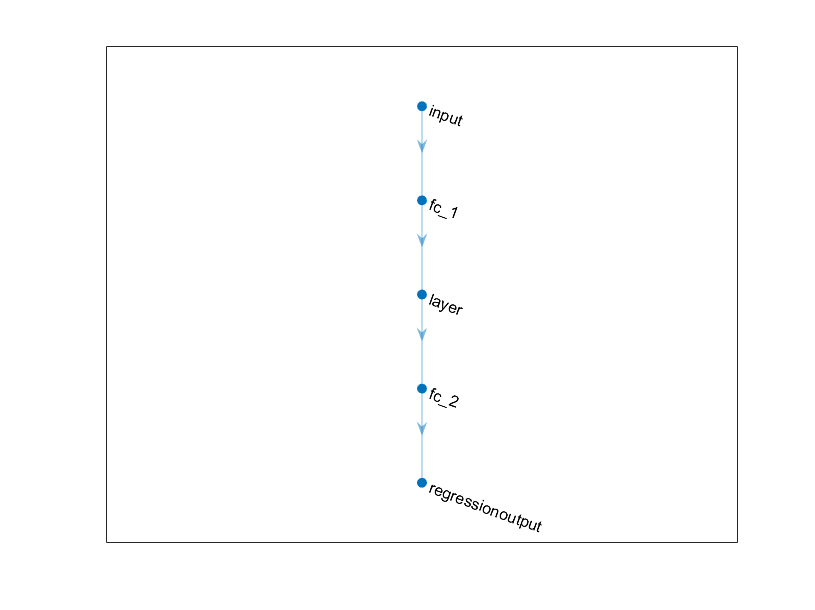

n = 10;                                        % input size
m = 20;                                        % output size 
num_neurons = 50;

layers = [featureInputLayer(n)                 % Input layer
          fullyConnectedLayer(num_neurons)     % Hidden layer
          sigmoidLayer                         % Activation
          fullyConnectedLayer(m)               % Output layer
          regressionLayer ];                   % loss layer

net = layerGraph (layers);
plot(net)

analyzeNetwork (net)

## Generate synthetic dataset

N = 100;                                 % N = number of samples
A = rand(m,n);                           % n = input size , m= output size
x = randn(n,N);                          % nxN matrix 
b = A*x + 0.1* randn (m,N);              % mxN matrix

xtrain = x';                             % xtrain is N x n = N points in R^n
btrain = b';                             % btrain is N x m = N points in R^m


## Training

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:03 |         8.95 |         40.0 |          0.1000 |
|      50 |          50 |       00:00:04 |         1.05 |          0.5 |          0.1000 |
|     100 |         100 |       00:00:05 |         0.56 |          0.2 |          0.1000 |
|     150 |         150 |       00:00:05 |         0.45 |      1.0e-01 |          0.1000 |
|     200 |         200 |       00:00:06 |         0.39 |      7.6e-02 |          0.1000 |
|     250 |         250 |       00:00:07 |         0.36 |      6.4e-02 |          0.1000 |
|     300 |         300 |       00:00:07 |         0.34 |      5.6

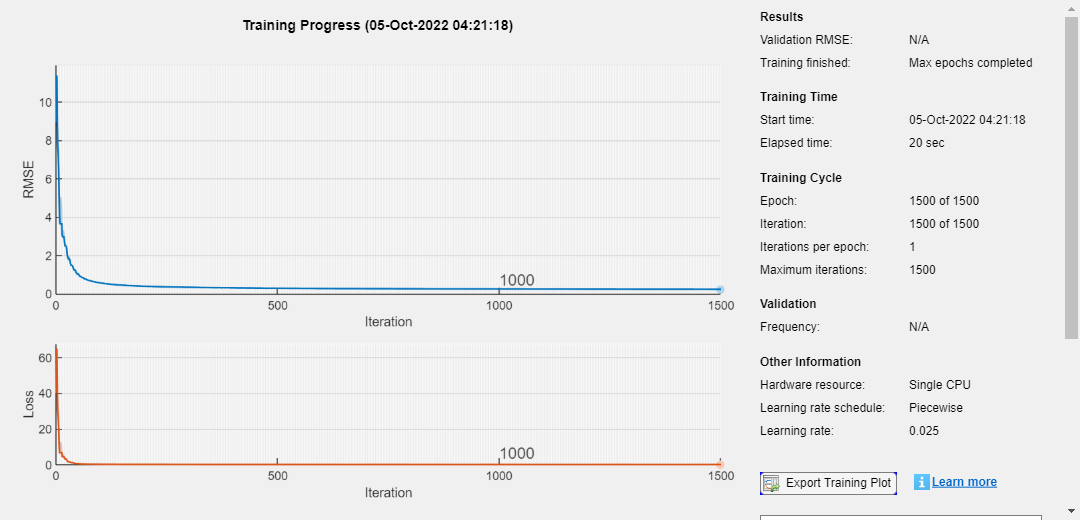

opt = trainingOptions("adam",  Plots="training-progress", ...
    InitialLearnRate=0.1, ...
    MaxEpochs=1500, ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropPeriod=600,...
    LearnRateDropFactor=0.5);

net = trainNetwork(xtrain,btrain,layers, opt);

Extract learnt parameters of fully connected layres:

W1 = net.Layers(2).Weights % Extract Weights of fc - layer 2

W1 = 50×10 single matrix
    0.6420    0.2309   -0.6450   -0.4243    0.7230   -0.4496   -0.0464    0.7908    0.0433    0.2425
   -0.6458   -0.2739   -0.4525   -0.0283    0.3912    0.1412   -0.3321   -1.1500   -0.7254    0.5591
   -0.4838    1.1503   -0.1380    0.9944    0.0660   -0.6390    1.2800    0.3238    0.9486    0.3757
    1.0796    0.2457   -0.0422    0.6702    0.5110   -0.3667   -0.2622   -0.2166   -0.7044   -0.9586
   -0.1463    0.1561    0.1336    0.1750    0.9456    0.8645   -0.9786    0.4577   -0.7432   -0.0712
   -0.6009    0.2576    0.8407   -0.5404    0.0257    0.6847   -0.7263   -0.9685    0.3881    0.0935
   -0.6173   -0.0097   -0.4689   -0.6666   -0.4936   -0.8234   -0.3456    0.0530   -0.0523   -0.9806
   -0.2312   -0.9876   -0.1774   -1.2761    0.2918   -0.7904   -0.3760   -0.3021   -0.9713   -0.0695
   -0.5658    0.7140    1.3084    0.6204   -0.2117    0.2332    0.8491    1.0173    0.5305    0.7768
   -0.1419    1.7919    0.4852   -0.5044    0.0737    0.0506   -0.

B1 = net.Layers(2).Bias

B1 = 50×1 single column vector
   -0.9139
   -1.4802
   -1.7616
   -1.0524
   -1.4068
   -0.7352
   -1.2364
   -2.0013
   -3.0218
   -1.2265


W2 = net.Layers(4).Weights % Extract Weights of fc - layer 4

W2 = 20×50 single matrix
    0.6147   -0.4673    0.6141    0.3577   -0.1259   -0.6589    0.0589   -0.4732    0.7954    0.5975    0.6525    0.5599   -0.4018    0.3814   -0.5064    0.0508    0.3348   -0.7838    0.0657   -0.4571   -0.5972    0.1229   -0.2210   -0.1140    0.1396    0.5297    0.6377   -0.6214    0.6679    0.0674   -0.4417    0.1477    0.3134    0.1213   -0.3347   -0.4501   -0.0766    0.3948    0.4661   -0.4241    0.0657   -0.3598   -0.2351    0.2799    0.0953    0.2919   -0.3414    0.3442   -0.3859   -0.0872
    0.2521    0.3996    0.5444    0.6002    0.5566   -0.7573   -0.5630   -0.4484    0.3617   -0.3460    0.0921   -0.3579   -0.3962   -0.1741   -0.1816    0.1059    0.2761   -0.5100    0.3195    0.0759   -0.1264   -0.1917    0.5119    0.0430   -0.1302    0.8017   -0.1117   -0.3812    0.3733   -0.2045   -0.2126    0.5203   -0.1019    0.3579   -0.0115   -0.4693    0.0762    0.0987   -0.0042    0.3216    0.7075   -0.2773   -0.3859    0.2482    0.0133    0.2597    0.3065   -

B2 = net.Layers(4).Bias

B2 = 20×1 single column vector
   -0.0852
   -0.2378
    0.2314
   -0.1560
   -0.1287
   -0.0312
   -0.2222
   -0.1937
    0.1707
    0.0805


## Prediction

xnew = rand(n,1);
b_predict = predict(net,xnew')'

b_predict = 20×1 single column vector
    3.1927
    2.2180
    3.0070
    3.0794
    1.3323
    3.0686
    2.1367
    2.9147
    3.5894
    2.9045


b_expected = A*xnew

b_expected =     2.9470
    2.2298
    2.8475
    2.9987
    1.3700
    2.8770
    2.1052
    2.7218
    3.4501
    2.8711



err = norm(b_predict-b_expected)

ans = single
0.6255

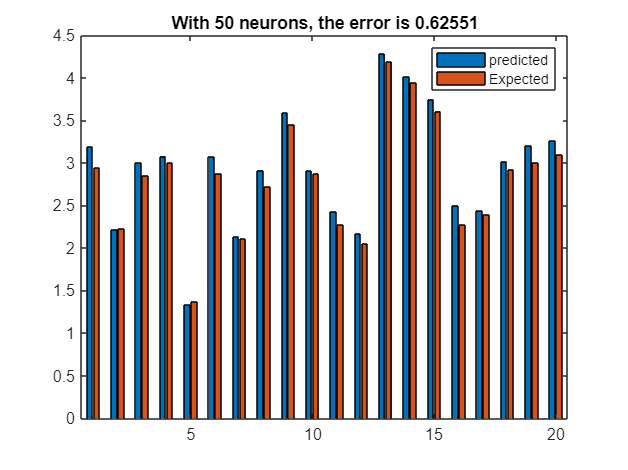


bar([b_predict,b_expected])
legend("predicted", "Expected")
title("With "+num_neurons + " neurons, the error is " + norm(b_predict-b_expected))